# The machine learning recipe

## Overview

Even if you haven't finished the Matlab Fundamentals, you should stop and have a read through this lab. (You can return to the Matlab Fundamentals afterwards.) What you'll hopefully find is that applying the machine learning recipe in Matlab is pretty easy. Don't worry if you don't understand every last detail of Matlab's syntax yet - that will come in time - but you should hopefully still find that there are relatively few lines of code, which are relatively easy to understand, and that match up pretty clearly with the steps we saw in lectures.

## The machine learning recipe: example

### Step 1: data collection

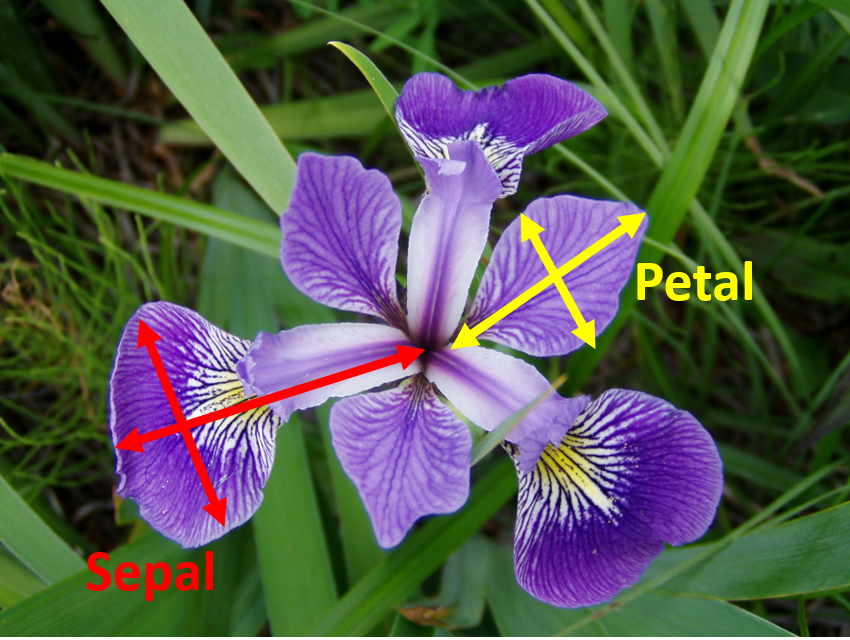

On this unit, we'll typically rely on datasets collected by other people. And often we'll work with quite simple "toy" datasets while we're learning about and understanding new concepts (see the lecture slides for further discussion).

Our main toy dataset in labs will be the iris.csv dataset (available on Moodle), which contains petal and sepal measurements (see the image above) for 150 different irises, each belonging to one of three different species. 

**Download the iris.csv dataset, open it up with Excel, and have a look at the data it contains.**

You'll notice that there are 4 numerical features containing the sepal/petal measurements (first 4 columns) and a final categorical feature containing the species (fifth column): 

- iris.csv: contains petal and sepal measurements (4 numerical features), plus iris species (1 categorical feature)

The iris.csv dataset is ideal for learning about and practicing with predictive models. We'll use it primarily in classification problems: trying to predict which species an iris belongs to, based on its petal/sepal sizes. But it's also possible to use it to formulate other problems too (e.g., regression problems where we try to predict one of the measurements) and we'll use the dataset quite a lot on the unit.

A classification problem based on just 4 features is fairly small; some of the other problems we'll work on have lots more features. But while we're still learning about machine learning techniques, even 4 features can be too many to think easily about (we'll talk about this a lot more in the upcoming lectures). For this reason we'll also work with two subsets of the iris.csv dataset:

- petal.csv: contains petal measurements only (2 numerical features), plus iris species (1 categorical feature)

- sepal.csv: contains sepal measurements only (2 numerical features), plus iris species (1 categorical feature)

(Note: just because a dataset contains fewer features doesn't mean the classification problem itself is easier - in general the more features we have for machine learning, the better; this just isn't always true when we're trying to *understand* new machine learning concepts.)

Between these three datasets we have enough data to introduce and learn about all the steps of the machine learning recipe, and also for you to try applying the recipe yourself.

Let's work through the remaining steps of the recipe in order to try and solve a predictive modelling problem based on the sepal.csv dataset:

- **Is it possible to predict the species an iris belongs to based on its sepal measurements?**

Because the target feature values are categorical, this is a classification problem.

### Step 2: data exploration and preparation

In the general case, step 2 of the machine learning recipe involves exploring your data in order to better understand it, and the kind of problem you're working on, and then preparing it for use in the remaining steps of the recipe. For us, the process is somewhat simpler because we will usually state the nature of the problem very clearly (as in the previous section) and we also make some guarantees about the kinds of datasets that we share. Below, we briefly summarise the general case for exploration and preparation (more detail is available in the lecture slides), and then we look at the sepal.csv dataset specifically.

In the general case, exploration involves establishing basic things like finding out how many features you have, which column the target feature values are in, what kind of problem you're dealing with (e.g., descriptive or predictive, classification or regression), and how many observations you have. Preparation involves performing the steps that are necessary before proceeding with the machine learning recipe, such as finding and removing any errors ("cleaning"), converting categorical predictive feature values into numerical ones, and dividing the data up (using the "splitting" operations we saw in the lecture) in preparation for "holdout testing".

On this unit things are simplified because we will typically tell you the problem you are working on very clearly (as in the previous section). You can also assume that all the datasets we share via Moodle have already been cleaned (unless we say otherwise), and this includes iris.csv, petal.csv and sepal.csv. Finally, you can assume that all predictive feature values (the feature values that we are predicting *from*) are numeric, or that we have already converted them to numeric values for you. 

We'll revisit these simplifying assumptions later in the unit, but for now they enable us to move swiftly on to the more interesting bits of the recipe.

So the only job we have with the sepal.csv dataset is to divide it up in readiness for using holdout testing in the later steps of the recipe. (Remember holdout testing helps us guard against overfitting.) There is more discussion in the lecture slides, but for a classification problem this essentially comes down to the following four operations:

- Shuffling the observations (to remove any ordering that may be present)

- Splitting the observations horizontally, into separate "testing observations" and "training observations" (here we set aside 40% for testing)

- Splitting the "testing observations" vertically, into "testing examples" and "testing labels"

- Splitting the "training observations" vertically, into "training examples" and "training labels"

In the code below, we show each of these steps being applied to the sepal.csv dataset:

rng(0); % re-seed Matlab's random number generator for repeatable results

% read in the dataset:
data = readcell('sepal.csv');

% have a look at the first 10 rows, and check we can spot the target feature values:
data(1:1:10, 1:1:end)

% read out the observations (while dropping the feature names):
obs = data(2:end,:);

% shuffle the observations to remove any ordering:
obs_shuffled = obs(randperm(size(obs,1)), :);

% we'll use 40% of them in our testing data, how many observations is that?:
nTest = round(0.4 * size(obs_shuffled,1))

% horizontal split...

% copy out our testing observations (first 40% of the data)...:
obs_test = obs_shuffled(1:1:nTest, :);
% ...and and our training observations (final 60% of the data):
obs_train = obs_shuffled(nTest+1:1:end, :);

% set the column index of the target feature values (identified visually,
% from the earlier output):
label_index = 3;

% vertical split 1:

% separate the examples and the labels for the testing observations:
test_labels = categorical(obs_test(:, label_index));
test_examples = cell2mat(obs_test(:, 1:end~=label_index));

% have a quick look at the sizes, as a sanity check
size(test_examples)
size(test_labels)

% vertical split 2:

% separate the examples and the labels for the training observations:
train_labels = categorical(obs_train(:, label_index));
train_examples = cell2mat(obs_train(:, 1:end~=label_index));

% have a quick look at the sizes, as a sanity check
size(train_examples)
size(train_labels)

The only bit of code that we didn't explicitly talk about in the Matlab fundamentals is the call to the `randperm()` function. You can probably figure out what it does from the way it's called, it's name, and the associated comment. But if you're not sure you can use the usual strategies taught in the fundamentals to figure it out. E.g., try calling it from the Command Window (try `randperm(5)` and then `randperm(10)`), or calling `help` on it, or Googling "Matlab randperm" to find Matlab's online documentation.

Before we move on, just note that you can access individual examples/labels using all the usual Matlab array notation. For example, here we copy the third training example into a variable called `temp` and display the individual feature values with a call to the `bar()` function:

temp = train_examples(3, 1:1:end)
figure;
bar(temp);

### Step 3: model training

Now we have our training data prepared, we're in a position to train a predictive model. All we need to do is to invoke a particular predictive model's training (or "fitting") phase, and hand it over our training data (plus any hyperparameters we want to specify, but this is optional). We'll typically just use the word "model" rather than predictive model, and we try to keep a letter "m" (for model) somewhere in the naming of the model's Matlab variable. Because we're looking at a classification problem here, the resulting model also gets the name "classifier". Matlab has a series of `fitc*()` functions for invoking the fitting phases of different classifiers (where the "fitc" stands for "fit classifier"). For example, have a look at the call for training a naive Bayes (NB) classifier, below:

% train a naive Bayes classifier:
m_nb = fitcnb(train_examples, train_labels)

We'll talk a more about the naive Bayes classifier in lectures, but just notice for now how easy it is to train one once you've prepared your data. As discussed in the lecture slides, the fitting algorithm for this classifier (and any other classifier) requires only:

- Your training examples

- Your training labels

- (Optionally, any other hyperparameters you want to supply)

Notice that it's an object we get back from the `fitcnb()` call (a `ClassificationNaiveBayes` object):

whos('m_nb')

And `fitcnb()` is one of the "intermediate" functions mentioned in the Matlab Fundamentals, which helps us to set up parameters ready for a call to a class constructor. It can accept various name-value pairs, as you might expect. (You can have a *quick* look at its [documentation](https://uk.mathworks.com/help/stats/fitcnb.html) if you're interested, but it's not the time to try and understand everything it can do just at the moment, so don't spend too long.)

### Step 4: model evaluation

Having trained a model, we are then ready to evaluate its performance on the testing data we separated out in step 2. This is the "holdout" approach to evaluation that we discussed in the lecture, which helps protect us from overfitting.

All we need to do is to invoke the prediction phase of the predictive model we have trained, and hand it over our testing data. All predictive model objects in Matlab have a `predict()` class for doing this. For example, here we pass our testing examples to the `predict()` method of the naive Bayes classifier in order to generate a set of predicted class labels:

% use the naive Bayes classifier to make predictions based on our testing examples:
predictions = m_nb.predict(test_examples)

We've left the semi-colon off the line above, so the predictions get printed out, but they are difficult to interpret in a big long array. We can easily generate a quantitative measure of performance by calculating the fraction of the predictions which are in agreement with their corresponding testing labels:

% calculate a measure of performance:
p_nb = sum(predictions == test_labels) / length(test_labels)

You should get 0.7167, or about 71.7% accuracy. I.e., 71.7% of the testing examples were assigned the correct label.

### Step 5: model improvement

In the final step of the recipe, we can investigate whether performance improvements are possible by adjusting hyperparameters, or perhaps considering different models altogether. Step 5 is really a repeating link back to step 3 (model training) and the recipe can involve iterating over the final few steps many times before a decision is made about which classifier (and what associated hyperparameter values) to use.

As an example, in the code below we train a k-nearest neighbours (k-NN) classifier with default hyperparameters. Again, don't worry just yet about how the classifier works (more in lectures soon), but just note again how easy the call is to make (and how similar it is to our earlier call to train the naive Bayes classifier), and note the general idea of step 5 of the recipe: make changes, re-train, re-evaluate, and compare:

% train a k-NN classifier:
m_knn = fitcknn(train_examples, train_labels)

% use the knn model to classify the testing data:
predictions = m_knn.predict(test_examples)

% calculate the overall classification accuracy:
p_knn = sum(predictions == test_labels) / length(test_labels)

You should see slightly higher accuracy at about 73.3%.

We won't spend hours looking for optimal performance on this unit, as we're more interested in understanding how the methods work. But if you were using machine learning in another context (e.g., at work, or as part of your final year project) then you might spend quite a lot of time on step 5.

## The machine learning recipe: you try (optional)

Have a go at this task if you're progressing well with the Matlab Fundamentals, or you've already finished them. Otherwise, switch back to the Matlab Fundamentals and aim to get them finished by the next lab. There will be more chances to review and practice with the recipe then.

You have a go at applying each of the steps of the recipe to the full iris.csv dataset. Stick with using the first 40% of your shuffled observations as testing data, and stick with training a naive Bayes classifier with default hyperparameters. It's fine to work by copying and pasting from what you've seen above. In step 5, see if performance is better or worse when using a k-NN classifier with default hyperparameters:

(**Sanity check**: because the iris.csv dataset contains more features, you should expect better accuracies from both classifiers)

rng(0); % please leave this re-seeding of the random number generator in place so we can compare results

% read in the dataset:
data = readcell('iris.csv');

% write your code on the lines below

